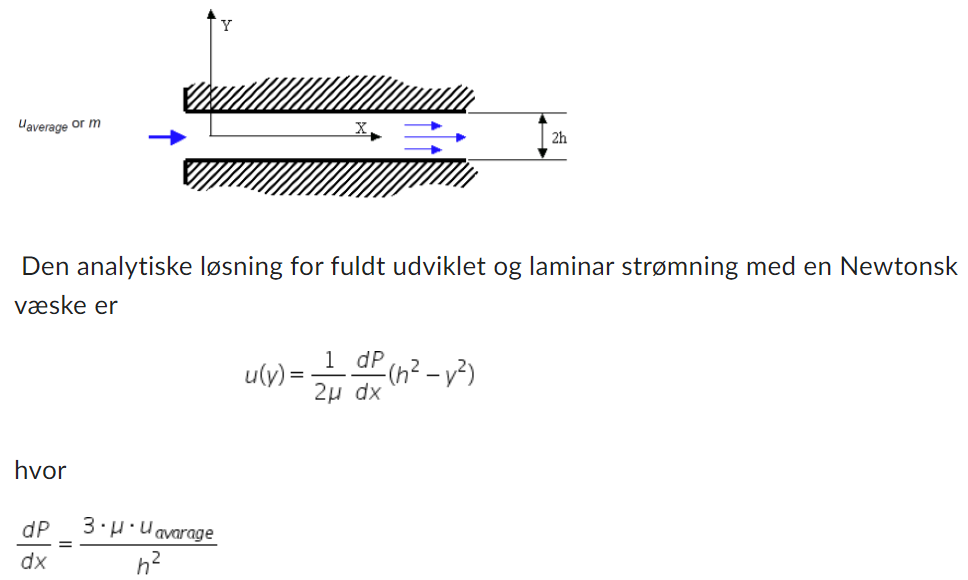

clear all
% Step size
stepSize = 0.0005;

% Number of steps on one side (excluding the middle 0)
numStepsOneSide = (21 - 1) / 2;

% Calculate the start and end values based on the number of steps and step size
startValue = -numStepsOneSide * stepSize;
endValue = numStepsOneSide * stepSize;

% Create the array
array = linspace(startValue, endValue, 21)

array =    -0.0050   -0.0045   -0.0040   -0.0035   -0.0030   -0.0025   -0.0020   -0.0015   -0.0010   -0.0005         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050




u_avg = 0.1; %m/s    
y = array%0.01-0.0005*11:0.0005:0.01+0.0005*11 %afstand fra origo i y-retningen

y =    -0.0050   -0.0045   -0.0040   -0.0035   -0.0030   -0.0025   -0.0020   -0.0015   -0.0010   -0.0005         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050


h = 0.01; %m
mu = 0.0010014; %Pa*s

u = 1/(2*mu) * (3*mu*u_avg / h^2) .* (h^2 - y.^2)

u =     0.1125    0.1196    0.1260    0.1316    0.1365    0.1406    0.1440    0.1466    0.1485    0.1496    0.1500    0.1496    0.1485    0.1466    0.1440    0.1406    0.1365    0.1316    0.1260    0.1196    0.1125


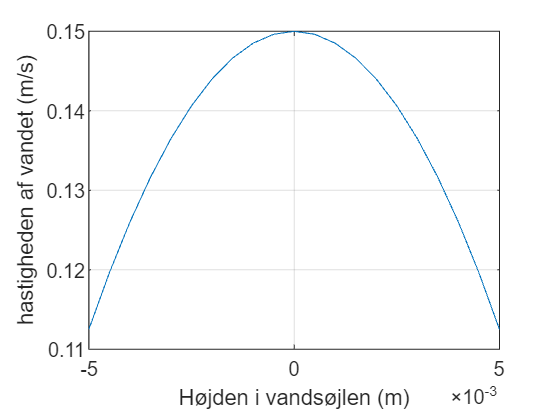


plot(y,u)
grid()%"minor"
xlabel("Højden i vandsøjlen (m)")
ylabel("hastigheden af vandet (m/s)")


max(u)

ans = 0.1500

Mesh 7

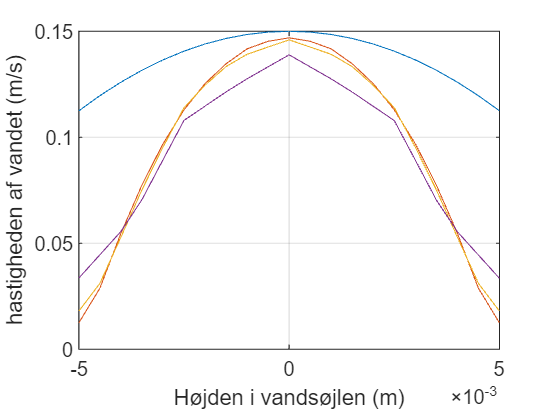

data = [
    0       0.012420892     0       0.033545341     0       0.017957796
    0.0005  0.028776541     0.0005  0.044553247     0.0005  0.031064114
    0.001   0.054673423     0.001   0.055561834     0.001   0.052834121
    0.0015  0.077450212     0.0015  0.070570398     0.0015  0.075239333
    0.002   0.09689085      0.002   0.089335473     0.002   0.095307189
    0.0025  0.112936118     0.0025  0.107963731     0.0025  0.113958227
    0.003   0.125303499     0.003   0.114678994     0.003   0.124534223
    0.0035  0.134674719     0.0035  0.121394256     0.0035  0.13335147
    0.004   0.141707312     0.004   0.127579599     0.004   0.139154464
    0.0045  0.145288356     0.0045  0.133249743     0.0045  0.142563768
    0.005   0.146905323     0.005   0.138888969     0.005   0.145963787
    0.0055  0.145287336     0.0055  0.133207826     0.0055  0.142553082
    0.006   0.141702504     0.006   0.127526117     0.006   0.139142377
    0.0065  0.134671267     0.0065  0.121324238     0.0065  0.133326856
    0.007   0.125301197     0.007   0.114594289     0.007   0.124506224
    0.0075  0.112934845     0.0075  0.107864341     0.0075  0.113933581
    0.008   0.096884975     0.008   0.08919398      0.008   0.095282263
    0.0085  0.077444507     0.0085  0.07041959      0.0085  0.075229792
    0.009   0.054670986     0.009   0.055425406     0.009   0.052828624
    0.0095  0.028775421     0.0095  0.044434372     0.0095  0.031065613
    0.01    0.012427189     0.01    0.03344346      0.01    0.017956044
];

u_mesh_7 = data(:,2);
u_mesh_3 = data(:,4);
u_mesh_5 = data(:,6);

plot(y,u)
hold on
plot(y,u_mesh_7)
plot(y,u_mesh_5)
plot(y,u_mesh_3)
grid()%"minor"
xlabel("Højden i vandsøjlen (m)")
ylabel("hastigheden af vandet (m/s)")
hold off

Beregner forskellen på level 7 og numerisk

afvigelse1 = (1 - u ./ u_mesh_7') *100

afvigelse1 =  -805.7321 -315.7032 -130.4593  -69.9479  -40.8802  -24.5173  -14.9210   -8.8734   -4.7935   -2.9849   -2.1066   -2.9856   -4.7970   -8.8762  -14.9231  -24.5187  -40.8887  -69.9604 -130.4696 -315.7194 -805.2731


afvigelse2 = (1 - u_mesh_7' ./ u) *100

afvigelse2 =    88.9592   75.9444   56.6084   41.1584   29.0177   19.6899   12.9837    8.1502    4.5742    2.8983    2.0631    2.8990    4.5774    8.1526   12.9853   19.6908   29.0220   41.1628   56.6103   75.9453   88.9536



avereage1 = mean(afvigelse1)

avereage1 = -135.2062

avereage2 = mean(afvigelse2)

avereage2 = 32.4784


(1- u(11) / u_mesh_7(11)) *100

ans = -2.1066

(1- u_mesh_7(11) / u(11)) *100

ans = 2.0631